clear; clc; close all

% Riproducibilità
rng(42);

% Immagini
path = fullfile('Dataset', 'Da usare');
imgs = imageDatastore(path, "IncludeSubfolders", true, "LabelSource", "foldernames");

# EDA

fprintf('Numero totale di immagini: %d\n', numel(imgs.Labels));

Numero totale di immagini: 50000


fprintf('Training: %d\n', numel(imgs.Labels) * 0.7);

Training: 35000


fprintf('Validazione: %d\n', numel(imgs.Labels) * 0.15);

Validazione: 7500


fprintf('Test: %d\n\n', numel(imgs.Labels) * 0.15);

Test: 7500



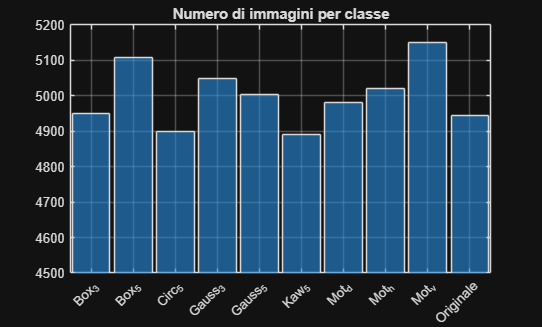


% Immagini per classe
figure;

histogram(imgs.Labels);

title('Numero di immagini per classe');
ylim([4500, 5200]);

ax = gca;
ax.YAxis.Exponent = 0;
ytickformat('%.0f')

xtickangle(45);

grid on;

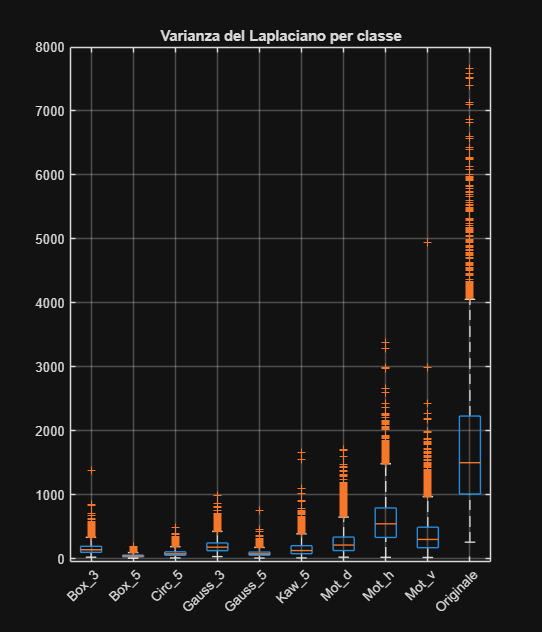



% Boxplot del laplaciano per classe
figure;

T = readtable('laplacian_values.csv', ...
    'Delimiter', ',', ...
    'ReadVariableNames', true, ...
    'VariableNamingRule', 'preserve');

boxplot(T.LapVariance, T.Label);
ylim([-50, 8000]);
set(gcf, 'Position', [100, 100, 600, 700]);

title('Varianza del Laplaciano per classe');

xtickangle(45);
grid on;

# Test accuratezza

% Servono solo quelle di test
[~ , imgsTemp] = splitEachLabel(imgs, 0.7, "randomized");
[~, imgsTest] = splitEachLabel(imgsTemp, 0.5, "randomized");

% Carica la rete
S = load('rete.mat');

% Mostra struttura
lgraph = layerGraph(S.layers);
figure;
plot(lgraph)

% Matrice di confusione
YPred = classify(S.net, imgsTest);
YTest = imgsTest.Labels;

accuracy = mean(YPred == YTest);

cm = confusionchart(YTest, YPred);
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
cm.XLabel = 'Classe predetta';
cm.YLabel = 'Classe reale';